# WorkSheet 8

Problem 1

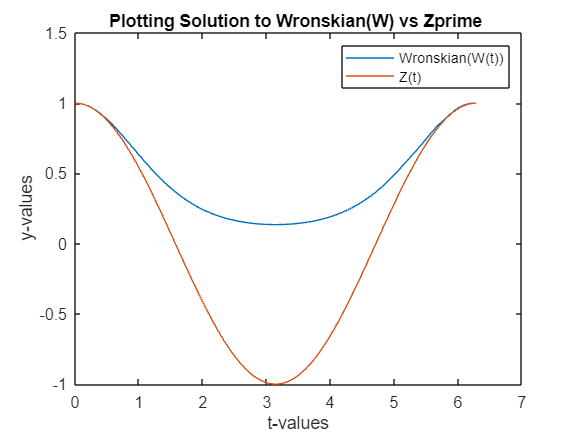

% Part A -- using Favorite ODE solver to approixmate: 
% y'' + sin(t)y'+ cost(t)y = 0 on all t over [0,2pi]
% Using ODE45 method

f_ode45 = @(t,v) [v(2); (-cos(t)).*v(1) - (sin(t)).*v(2)];

% saving solution for y1(t)
% y1(0) = 1 and y1'(0) = 0 
v0 = [1, 0];
tspan = linspace(0,(2*pi));
[t,v_1] = ode45(f_ode45,tspan,v0);

% saving solution for y2(t)
%y2(0) = 1 and y2'(0) = 1
v00 = [1, 1];   
tspan = linspace(0, (2*pi));
[t,v_2] = ode45(f_ode45,tspan,v00);

% Part B - Writing out the Wronskian (see handwritten work for how
% I calculated W )
W = v_1(:,1).*v_2(:,2) - v_2(:,1).*v_1(:,2);

%Part C -- Using ODE45 to approximate the DE z'+ sin(t)z = 1 on all t over
% [0, 2pi] with z(0) = 1 -- note handwritten work on uploaded pdf
f_B = @(t,z)[-1.*(sin(t))];
z0 = [1];
tspan = linspace(0,(2*pi));
[t,z] = ode45(f_B, tspan, z0);

% Part D -- Plotting Wronskian(W) and Z
figure()
plot(t,W)
hold on 
plot(t,z)
hold off
xlabel('t-values');
ylabel('y-values');
legend('Wronskian(W(t))','Z(t)');
title('Plotting Solution to Wronskian(W) vs Zprime ');

% our graph for the Wronskian of our  2nd order ODE closely resembles our graph for for the solution Z(t) to the 1st order ODE of dz/dt. 


% Part F -- Extra Credit
% Explanation of graphs: we are able to use Abel's identity in order to
% transform a 2nd order ODE into a 1st order linear DE. In turn, this is how we can approximate a solution which yields a graph that is similar to our "analytic" solution in this case, which is a 1st order linear ODE in the form of dz/dt = -1sin(t). If you observe the given equation of y'' + sin(t)y' + cos(t)y = 0, it looks very similar to our equation for dz/dt just if we were to continue differentiating. The theory of differential equations essentially tells us that by transforming equations of a higher order into a linear equation, this new equation serves as a linear approximation for the actual solution.

Problem 2

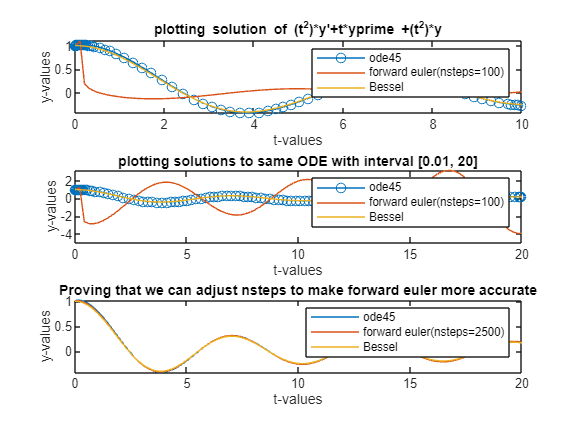

% Part A
f_1 = @(t,v) [v(2); (((-1)./t).*v(2)) - v(1)];
ic_ode45 = [1, 1];
tspan = [0.01 10];
[t_ode45,y_ode45] = ode45(f_1,tspan,ic_ode45);

% Part B
ic_euler = [1, 1];
nsteps = 100;
[t,v] = forward_euler_vec(f_1,tspan,ic_euler,nsteps);

% Part C -- plotting ode45 and forward_euler, then comparing these plots to he solution plotted using besselj Matlab function
% setting up besselj function:
nu = 0;
z = 0:0.1:10;
bess_function = besselj(nu,z);
figure()
subplot(3,1,1)
plot(t_ode45,y_ode45(:,1),'o-')
hold on
plot (t,v(:,1))
plot(z,bess_function)
xlabel('t-values')
ylabel('y-values')
title('plotting solution of (t^2)*y''+t*yprime +(t^2)*y')
legend('ode45','forward euler(nsteps=100)', 'Bessel');

% Part D -- Approximating solutions from the IVP over the new interval [0.01, 20]
tspan2 = [0.01, 20];
% ode45:
[t_ode452,y_ode452] = ode45(f_1,tspan2,ic_ode45);
% forward euler:
[t2,v2] = forward_euler_vec(f_1,tspan2,ic_euler,nsteps);
%besselj:
z2 = 0:0.1:20;
bess_function2 = besselj(nu, z2);
subplot(3,1,2)
plot(t_ode452,y_ode452(:,1),'o-')
hold on
plot (t2,v2(:,1))
plot(z2,bess_function2)
xlabel('t-values')
ylabel('y-values')
title('plotting solutions to same ODE with interval [0.01, 20]')
legend('ode45','forward euler(nsteps=100)', 'Bessel')

% The ode45 and besselj functions look similar, while the forward euler differs between them both significantly. Since the besselj function represents the analytics solution, then ode45 is the better approximataion. 

% Part E -- explaining whether we can adjust nsteps so that the forward euler gets closer to the actual approximation 
% Yes, by significantly increasing the number of steps in the forward_euler function, we get closer to the actual approximation of the solution. This is because as we increase the nsteps, we decrease the size of the error of forward euler, which is an operation that truncates after the first term in the Taylor series. This is proven in our third graph (the code below), where you can observe that our forward_euler plots very closely to the ODE45 and Bessel function plots.
nsteps2 = 2500;
% forward euler:
[t3,v3] = forward_euler_vec(f_1,tspan2,ic_euler,nsteps2);

subplot(3,1,3)
plot(t_ode452,y_ode452(:,1))
hold on
plot (t3,v3(:,1),'')
plot(z2,bess_function2)
xlabel('t-values')
ylabel('y-values')
title('Proving that we can adjust nsteps to make forward euler more accurate')
legend('ode45','forward euler(nsteps=2500)', 'Bessel')

Problem 3

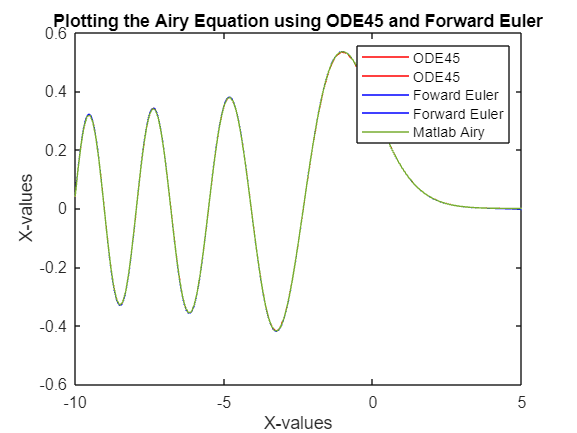

% Part A: solving the equation y'' - ty = 0 over all x [-10,5] with given
% Using ODE45
f_Airy = @(t,v) [v(2); t.*v(1)];
IC = [((1/((3^(2/3))*gamma(2/3)))), ((-1/((3^(1/3))*gamma(1/3))))];
t1 = [0,5];
t2 = (-1).*[0,10];
tspan = (t1-t2);
[t_ode45P,y_ode45P] = ode45(f_Airy,t1,IC);
[t_ode45N,y_ode45N] = ode45(f_Airy,t2,IC);
% Using forward_euler -- note, nsteps must be very high (i.e. >100,000)
% otherwise the forward euler plot has a tail at end of interval that
% deviates from ode45
nsteps = 100000;
[t,v] = forward_euler_vec(f_Airy,t1,IC,nsteps);
[t2,v2] = forward_euler_vec(f_Airy,t2,IC,nsteps);

% Part B:
figure()
plot(t_ode45P,y_ode45P(:,1),"Color",'r')
hold on
plot(t_ode45N,y_ode45N(:,1),"Color",'r')
plot(t,v(:,1),"Color",'b')
plot(t2,v2(:,1),"Color",'b')

% Part C: Plotting the actual solution using MATLAB's Airy Function
x= -10:0.1:5;
ai = real(airy(x));
plot(x,ai)
xlabel('X-values')
ylabel('X-values')
title('Plotting the Airy Equation using ODE45 and Forward Euler')
legend('ODE45','ODE45','Foward Euler','Forward Euler', 'Matlab Airy');
hold off